# Atividade 05_03

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## Filtro Gaussiano

Usar as funções imfilter e fspecial ou a função imgaussfilt, para aplicar o filtro Gaussiano nas imagens de RM b5s.40.bmp e b5s.100. Utilize dois valores de sigma diferentes à sua escolha, e observe como o sigma atua na intensidade da suavização. Mostre as imagens de entrada e de saída (in vs. out).

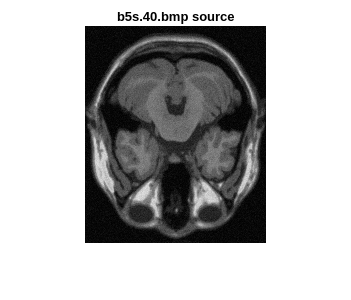

img1 = imread("b5s.40.bmp");
img2 = imread("b5s.100.bmp");

kernel1 = fspecial("gaussian", [5 5], 1);
kernel2 = fspecial("gaussian", [5 5], 3);

img1Kernel1 = imfilter(img1, kernel1);
img1Kernel2 = imfilter(img1, kernel2);

img2Kernel1 = imfilter(img2, kernel1);
img2Kernel2 = imfilter(img2, kernel2);

figure, imshow(img1)
title("b5s.40.bmp source")

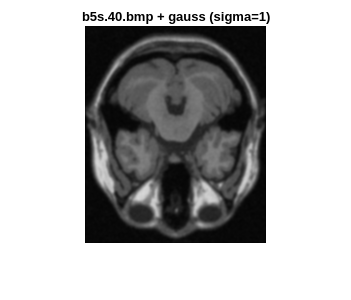


figure, imshow(img1Kernel1)
title("b5s.40.bmp + gauss (sigma=1)")

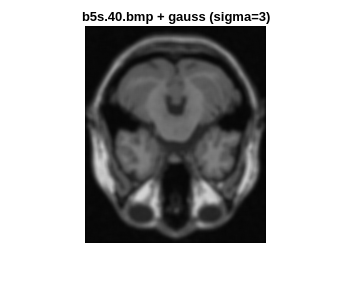


figure, imshow(img1Kernel2)
title("b5s.40.bmp + gauss (sigma=3)")

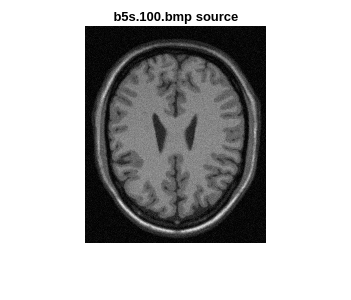


figure, imshow(img2)
title("b5s.100.bmp source")

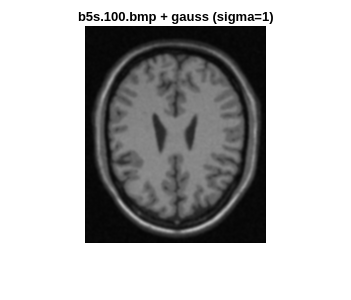


figure, imshow(img2Kernel1)
title("b5s.100.bmp + gauss (sigma=1)")

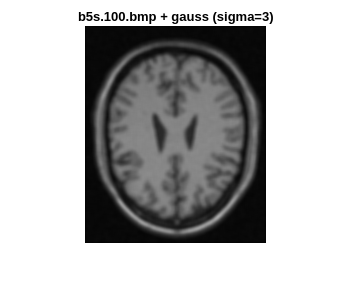


figure, imshow(img2Kernel2)
title("b5s.100.bmp + gauss (sigma=3)")